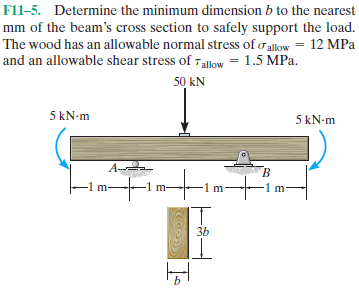

# symbolic units class

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 1*u.m);
b = b.add('reaction', 'force', 'Rb', 3*u.m);
b = b.add('applied', 'moment', 5*u.kN*u.m, 0);
b = b.add('applied', 'force', -50*u.kN, 2*u.m);
b = b.add('applied', 'moment', -5*u.kN*u.m, 4*u.m);
b.L = 4*u.m;

# section properties

B = sym('B', 'positive');
H(B) = 3*B;
b.I = B*H^3/12;
A = B*H;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{10\,\left(x-1\,m\right)\,\left(x+2\,m\right)}{9\,B^{4}\,\text{E}}\,\mathrm{kN}\,m & \text{ if }x\leq m\\ -\frac{10\,\left(x-1\,m\right)\,\left(-5\,x^{2}+13\,x\,m+m^{2}\right)}{27\,B^{4}\,\text{E}}\,\mathrm{kN} & \text{ if }x\in \left(m,2\,m\right]\\ -\frac{10\,\left(x-3\,m\right)\,\left(5\,x^{2}-27\,x\,m+27\,m^{2}\right)}{27\,B^{4}\,\text{E}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,3\,m\right]\\ -\frac{10\,\left(x-3\,m\right)\,\left(x-6\,m\right)}{9\,B^{4}\,\text{E}}\,\mathrm{kN}\,m & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{10\,\left(2\,x+m\right)}{9\,B^{4}\,\text{E}}\,\mathrm{kN}\,m & \text{ if }x\leq m\\ \frac{10\,\left(x-2\,m\right)\,\left(5\,x-2\,m\right)}{9\,B^{4}\,\text{E}}\,\mathrm{kN} & \text{ if }x\in \left(m,2\,m\right]\\ -\frac{10\,\left(x-2\,m\right)\,\left(5\,x-18\,m\right)}{9\,B^{4}\,\text{E}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,3\,m\right]\\ -\frac{10\,\left(2\,x-9\,m\right)}{9\,B^{4}\,\text{E}}\,\mathrm{kN}\,m & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -5\,\mathrm{kN}\,m & \text{ if }x\leq m\\ 5\,\left(5\,x-6\,m\right)\,\mathrm{kN} & \text{ if }x\in \left(m,2\,m\right]\\ -5\,\left(5\,x-14\,m\right)\,\mathrm{kN} & \text{ if }x\in \left(2\,m,3\,m\right]\\ -5\,\mathrm{kN}\,m & \text{ if }3\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq m\\ 25\,\mathrm{kN} & \text{ if }x\in \left(m,2\,m\right]\\ -25\,\mathrm{kN} & \text{ if }x\in \left(2\,m,3\,m\right]\\ 0 & \text{ if }3\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

addvar(y);

# reactions

Ra = r.Ra %#ok

$$Ra = 25\,\mathrm{kN}$$

Rb = r.Rb %#ok

$$Rb = 25\,\mathrm{kN}$$

clear Ra Rb;

# shear and moment diagram

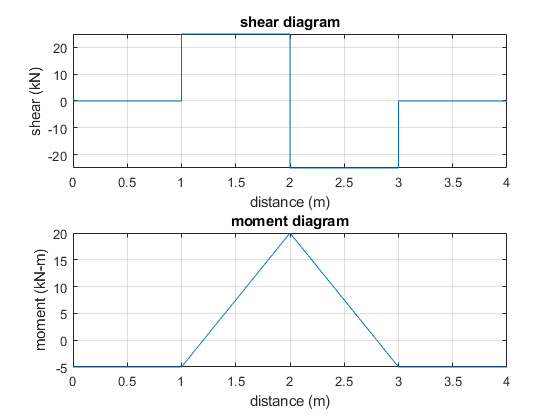

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# minimum dimension B

% -----------------------
% allowable stresses
sigma_allow = 12*u.MPa;
tau_allow = 1.5*u.MPa;
% -----------------------
% design for bending
M_max = m(2*u.m);
C = H/2;
sigma_max = rewrite(M_max*C/b.I, [u.MPa u.mm]);
Bsol.bending = simplify(solve(sigma_allow == sigma_max));
Bsol_bending_vpa = vpa(Bsol.bending, 5) %#ok

$$Bsol\_bending\_vpa = 103.57\,\mathrm{mm}$$

% -----------------------
% design for shear
V_max = v(1.5*u.m);
tau_max = rewrite(3*V_max/(2*A), [u.MPa u.mm]);
Bsol.shear = simplify(solve(tau_allow == tau_max));
Bsol_shear_vpa = vpa(Bsol.shear, 4) %#ok

$$Bsol\_shear\_vpa = 91.29\,\mathrm{mm}$$

% -----------------------
% minimum diameter
Bsol.limit = symmax([Bsol.bending Bsol.shear]);
clear Bsol_bending_vpa Bsol_shear_vpa;
setassum(old_assum);
% -----------------------